
clear;clc;close all;
set(0,'defaultlinelinewidth',3)
set(0,'defaultaxeslinewidth',2);
set(0,'defaultaxesfontsize',28);
set(0,'defaulttextfontsize',28);
set(0,'DefaultLineMarkerSize',28);
set(0,'Defaultaxesfontname','Times New Roman');
% addpath('./circleData');

% figure(); box on;
% plot(x/D,U0_axi,'-');
% xlabel('$x/D$','interpreter','latex');
% ylabel('$U_0$','interpreter','latex');
% set(gcf,'unit','centimeters','position',[20 20 20 20])

% saveas(gcf,'Re_80_U0_axi','epsc')


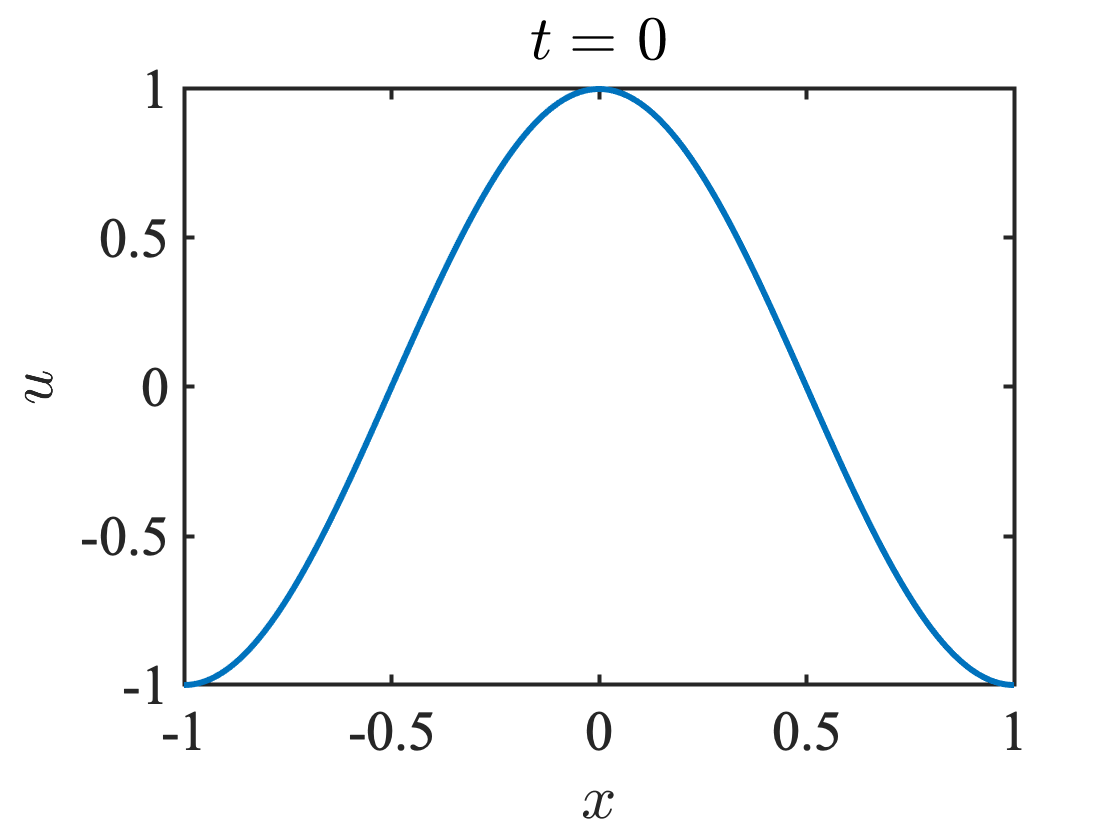

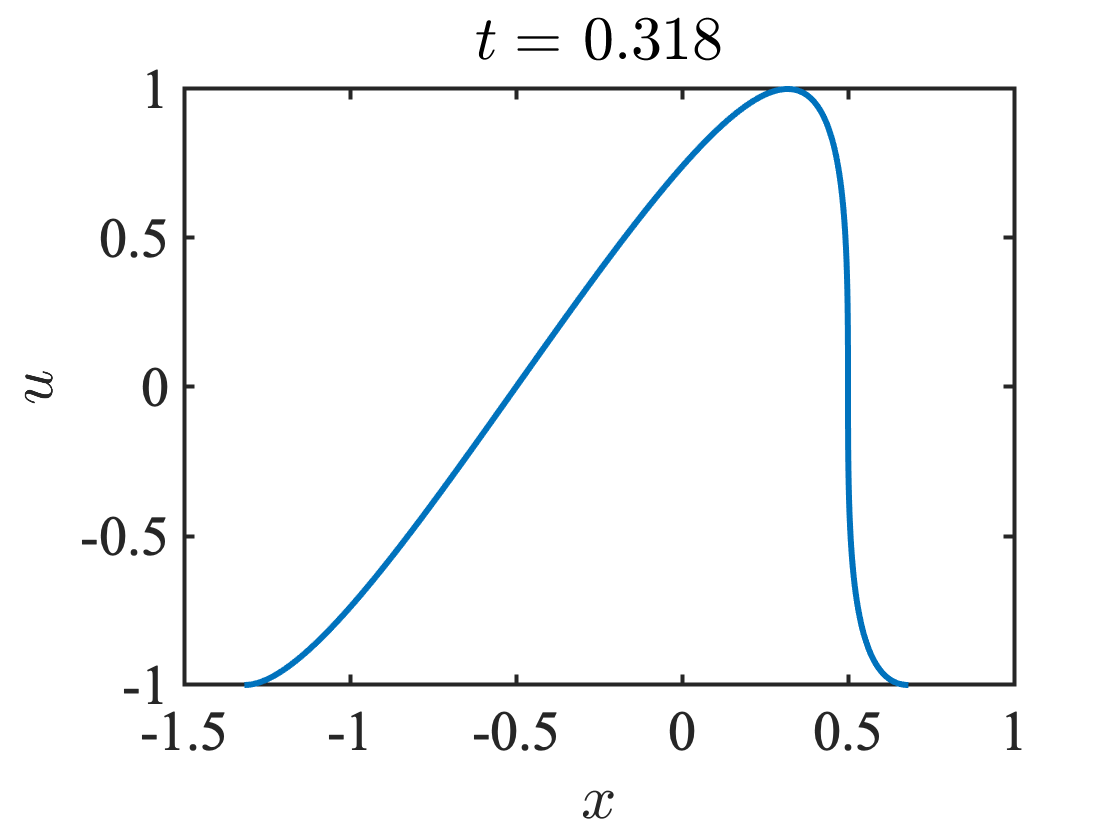


num = 1000;

aviobj=VideoWriter('burgers.avi');
open(aviobj);

% x0 = linspace(-1,1,num);
% x = x0;
% y = cos(pi*x0);
% t = 0;
% plot(x,y)
% xlim([-1.5 1])
% xlabel('$x$','interpreter','latex');
% ylabel('$u$','interpreter','latex');
% title(['$t=\ $',num2str(t)],'interpreter','latex');
% 
% saveas(gcf,'0','epsc')
fig = figure;
xlim([-1.5 1])
for t = 0:0.002:1/pi
    x = x0 + t * y;
    
    
    plot(x,y)
    
    xlabel('$x$','interpreter','latex');
    ylabel('$u$','interpreter','latex');
    title(['$t=\ $',num2str(t)],'interpreter','latex');
    drawnow
    currFrame = getframe(fig);
    writeVideo(aviobj,currFrame);
end

close(aviobj); %关闭
% saveas(gcf,'1','epsc')



























